# 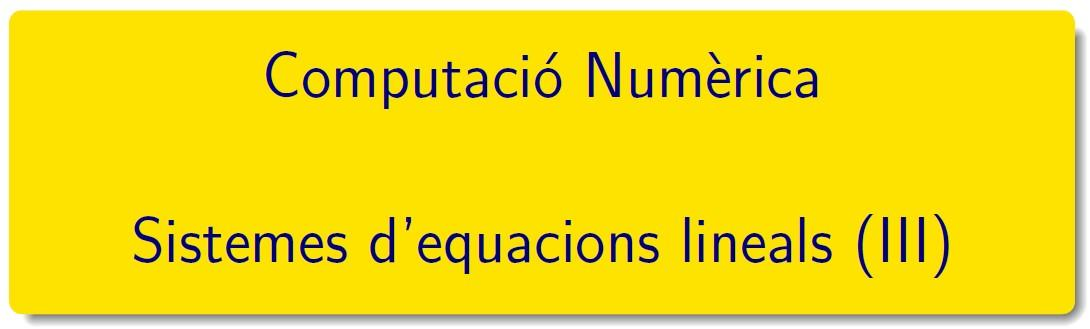

============================================================================

# Pràctica 5. Mètode de les potències. 

## 2.2 Valors i vectors propis d'una matriu. Mètode de la potència.

### Part I. Algorismes i joc de proves

#### Exemple 1. Mètode de la potència per al valor propi de mòdul més gran

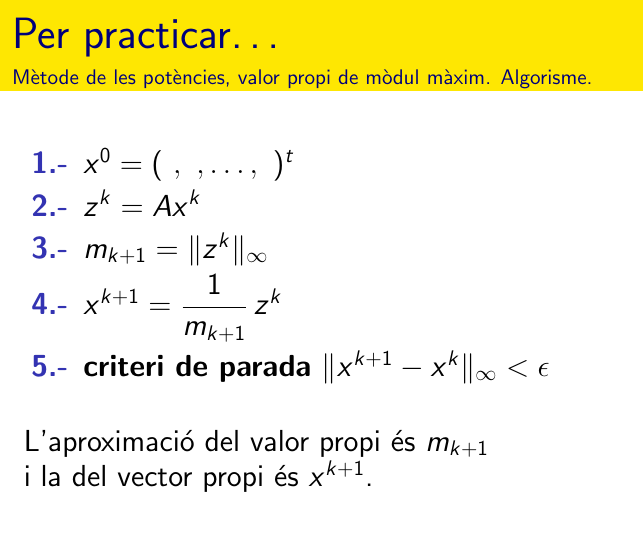                            

Calculeu, amb quatre xifres significatives, el valor propi dominant de la matriu:       $A=\left (\begin{array}{rrr}
1 & 0 & -1 \\
1 & 2 & 1 \\
2 & 2 & 3
\end{array} \right)$  

Proveu amb $x^0_{max}=\left (\begin{array}{r} 0 \\ 0\\ 1 \end{array} \right)\,,\quad   x^0_{min}=\left (\begin{array}{r} 1 \\ -1\\ 1 \end{array} \right)\$

A = [1 0 -1; 1 2 1; 2 2 3]

A =      1     0    -1
     1     2     1
     2     2     3


valors_vap = roots(poly(A))   % mètode teòric: polinomi característic

valors_vap =             3
            2
            1


x = [0, 0 ,1]';
% quatre xifres significatives --> 0.5e-4 fita de l'error relatiu aproximat
diff = Inf;
it = 0;

while diff > 0.5e-4 && it < 100
    z = A*x;
    norma = norm(z, Inf);
    x_new = 1/norma*z;
    diff = norm(abs(x_new-x), Inf);
    x = x_new;
    it = it + 1;
end
x, it, diff

x =      -0.49999
      0.49999
            1


it =     10


diff =    1.6935e-05


#### Exemple 2. Mètode de la potència per al valor propi de mòdul més petit

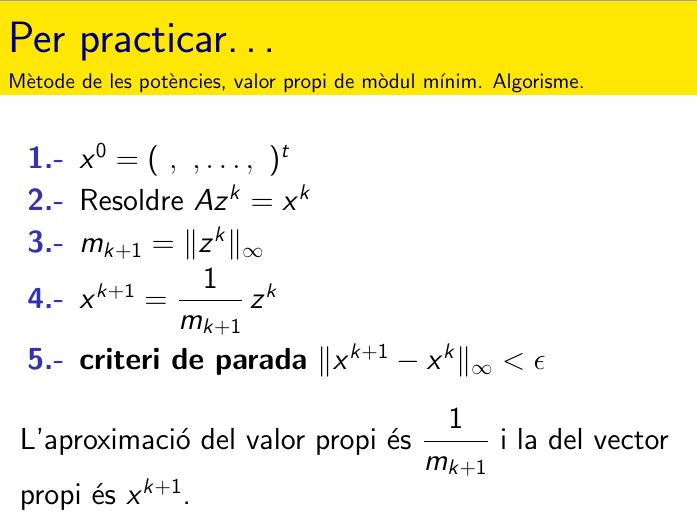

clearvars
A = [1 0 -1; 1 2 1; 2 2 3]

A =      1     0    -1
     1     2     1
     2     2     3


x = [1, -1, 1]';
% quatre xifres significatives --> 0.5e-4 fita de l'error relatiu aproximat
diff = Inf;
it = 0;

while diff > 0.5e-4 && it < 100
    z = A*x;
    norma = norm(z, Inf);
    x_new = 1/norma*z;
    diff = norm(abs(x_new-x), Inf);
    x = x_new;
    it = it + 1;
end
x, it, diff

x =      -0.49999
      0.49999
            1


it =     11


diff =    1.6935e-05


#### Exemple 3. Afegim el criteri del quocient de Rayleigh 

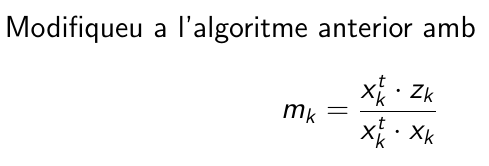

clearvars
A = -[1 0 -1; 1 2 1; 2 2 3]

A =     -1     0     1
    -1    -2    -1
    -2    -2    -3


x = [1, -1, 1]';
% veure MPRayleigh.html
% quatre xifres significatives --> 0.5e-4 fita de l'error relatiu aproximat
diff = Inf;
it = 0;

while diff > 0.5e-4 && it < 100
    z = A*x;
    norma = (x.'*z) / (x.'*x);
    x_new = 1/norma*z;
    diff = norm(abs(x_new-x), Inf);
    x = x_new;
    it = it + 1;
end
x, it, diff

x =       -1.3649
       1.3649
       2.7299


it =     11


diff =    3.0822e-05


### Part II. Practiquem ...

#### Exercici 1.  Valors propis de mòdul màxim i mínim. 

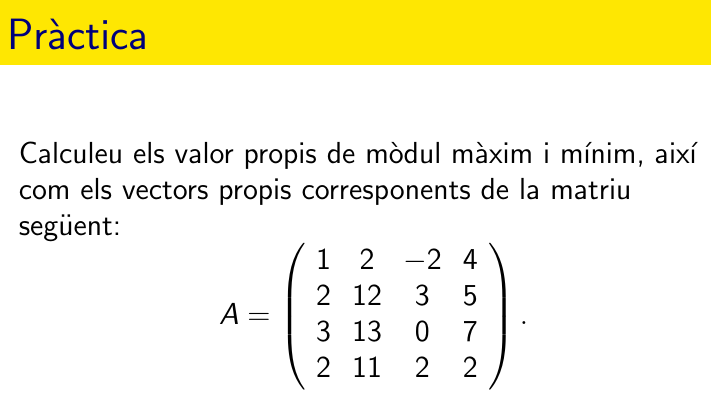

% veure practica5_exercici1.html
A = [1 2 -2 4; 2 12 3 5; 3 13 0 7; 2 11 2 2]

A =      1     2    -2     4
     2    12     3     5
     3    13     0     7
     2    11     2     2


valors_vap = roots(poly(A))   % mètode teòric: polinomi característic

valors_vap =        19.182
      -2.4531
      -1.7411
     0.012206


x = [1, 0, 0, 1]';
% quatre xifres significatives --> 0.5e-4 fita de l'error relatiu aproximat
diff = Inf;
it = 0;

while diff > 0.5e-4 && it < 100
    z = A*x;
    norma = norm(z, Inf);
    x_new = 1/norma*z;
    diff = norm(abs(x_new-x), Inf);
    x = x_new;
    it = it + 1;
end
x, it, diff

x =       0.17191
            1
      0.98748
      0.77516


it =      7


diff =    2.2621e-05


#### Exercici 2.  Quocient de Rayleigh 

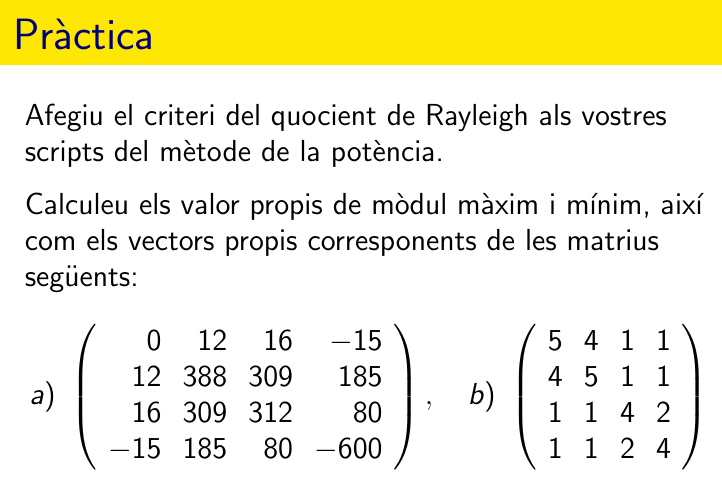

% veure practica5_exercici2.html
A = [ 5 4 1 1; 4 5 1 1; 1 1 4 2; 1 1 2 4]

A =      5     4     1     1
     4     5     1     1
     1     1     4     2
     1     1     2     4


x = [1, 0, 0, 1]';
% veure MPRayleigh.html
% quatre xifres significatives --> 0.5e-4 fita de l'error relatiu aproximat
diff = Inf;
it = 0;

while diff > 0.5e-4 && it < 100
    z = A*x;
    norma = (x.'*z) / (x.'*x);
    x_new = 1/norma*z;
    diff = norm(abs(x_new-x), Inf);
    x = x_new;
    it = it + 1;
end
x, it, diff

x =        1.1363
       1.1363
      0.56819
      0.56819


it =     13


diff =    4.6237e-05


## 2.2 Valors i vectors propis d'una matriu. Mètode QR.

### Part I. Algorismes i joc de proves

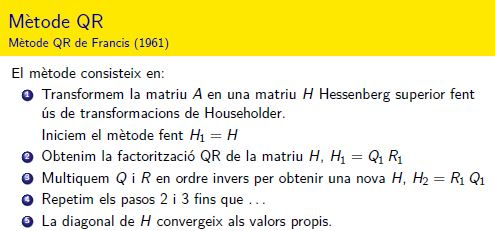

% veure MetodeQR.html
A = [0 12 16 -15;12 388 309 185;16 309 312 80;-15 185 80 -600]

A =      0    12    16   -15
    12   388   309   185
    16   309   312    80
   -15   185    80  -600


A = rosser

A =    611   196  -192   407    -8   -52   -49    29
   196   899   113  -192   -71   -43    -8   -44
  -192   113   899   196    61    49     8    52
   407  -192   196   611     8    44    59   -23
    -8   -71    61     8   411  -599   208   208
   -52   -43    49    44  -599   411   208   208
   -49    -8     8    59   208   208    99  -911
    29   -44    52   -23   208   208  -911    99


format shortG
diag(schur(A))

ans =         -1020
   3.1595e-13
     0.098049
         1000
         1000
       1019.9
         1020
         1020


%A = [1 0 -1; 1 2 1; 2 2 3]
H = hess(A)

H =          1000   2.0221e-07            0            0            0            0            0            0
   2.0221e-07         1020    -0.001095            0            0            0            0            0
            0    -0.001095         1001       137.98            0            0            0            0
            0            0       137.98       19.117      0.72302            0            0            0
            0            0            0      0.72302       1001.3       -27.72            0            0
            0            0            0            0       -27.72       -10.59       326.93            0
            0            0            0            0            0       326.93      -89.804       960.45
            0            0            0            0            0            0       960.45           99


k = 0;
while(k <150)
    k=k+1;
    [Q,R]=qr(H);
    H = R*Q;
    norm(tril(H,-1),'inf')
    sum(diag(abs(H)));
end

ans =        1010.7


ans =        1012.9


ans =        1012.6


ans =        1012.3


ans =          1012


ans =        1011.6


ans =        1011.3


ans =        1010.9


ans =        1010.5


ans =        1010.1


ans =        1009.7


ans =        1009.3


ans =        1008.8


ans =        1008.3


ans =        1007.8


ans =        1007.2


ans =        1006.6


ans =          1006


ans =        1005.4


ans =        1004.7


ans =          1004


ans =        1003.2


ans =        1002.4


ans =        1001.6


ans =        1000.7


ans =        999.81


ans =        998.85


ans =        997.83


ans =        996.76


ans =        995.64


ans =        994.46


ans =        993.22


ans =        991.91


ans =        990.54


ans =        989.11


ans =         987.6


ans =        986.02


ans =        984.36


ans =        982.63


ans =        980.81


ans =         978.9


ans =         976.9


ans =        974.82


ans =        972.63


ans =        970.35


ans =        967.97


ans =        965.48


ans =        962.88


ans =        960.17


ans =        957.34


ans =         954.4


ans =        951.33


ans =        948.15


ans =        944.83


ans =        941.39


ans =        937.82


ans =        934.11


ans =        930.26


ans =        926.28


ans =        922.16


ans =        917.89


ans =        913.48


ans =        908.93


ans =        904.23


ans =        899.39


ans =         894.4


ans =        889.26


ans =        883.97


ans =        878.54


ans =        872.96


ans =        867.24


ans =        861.37


ans =        855.36


ans =        849.21


ans =        842.92


ans =         836.5


ans =        829.94


ans =        823.25


ans =        816.44


ans =         809.5


ans =        802.43


ans =        795.26


ans =        787.97


ans =        780.57


ans =        773.07


ans =        765.47


ans =        757.78


ans =           750


ans =        742.13


ans =        734.19


ans =        726.17


ans =        718.09


ans =        709.94


ans =        701.74


ans =        693.49


ans =         685.2


ans =        676.86


ans =        668.49


ans =         660.1


ans =        651.68


ans =        643.24


ans =        634.79


ans =        626.34


ans =        617.89


ans =        609.44


ans =        600.99


ans =        592.57


ans =        584.16


ans =        575.77


ans =        567.42


ans =        559.09


ans =         550.8


ans =        542.55


ans =        534.34


ans =        526.19


ans =        518.08


ans =        510.03


ans =        502.03


ans =        494.09


ans =        486.22


ans =        478.42


ans =        470.68


ans =        463.01


ans =        455.41


ans =        447.89


ans =        440.45


ans =        433.08


ans =         425.8


ans =        418.59


ans =        411.47


ans =        404.43


ans =        397.48


ans =        390.61


ans =        383.82


ans =        377.13


ans =        370.52


ans =           364


ans =        357.57


ans =        351.22


ans =        344.96


ans =         338.8


ans =        332.72


ans =        326.73


ans =        320.82


ans =        315.01


ans =        309.28


ans =        303.64


ans =        298.09


ans =        292.63


ans =        287.25


format shortG
T = H

T =          1000   3.9714e-06  -2.2698e-24   2.5638e-27  -2.2287e-26   3.6372e-26   8.3436e-25   7.3204e-26
   3.9714e-06         1020   -0.0010752   3.3777e-21   -2.284e-19   2.7679e-19   6.2609e-18   5.5984e-19
            0   -0.0010752         1020     0.031106   3.6498e-15  -2.0254e-15  -4.0317e-14  -3.8697e-15
            0            0     0.031106       1019.2      -21.602  -2.3973e-13  -4.8914e-14  -9.4004e-14
            0            0            0      -21.602      -978.12       287.25   8.2091e-14   2.9318e-13
            0            0            0            0       287.25       958.79   1.4428e-13   7.8723e-15
            0            0            0            0            0            0     0.098049   1.0012e-14
            0            0            0            0            0            0            0   4.1391e-14


norm(tril(T,-1),'inf')

ans =        287.25


sum(diag(abs(T)))

ans =        5996.2


% veure MetodeQR.html

### Part II. Practiquem ...

#### Exercici 3.  Mètode QR

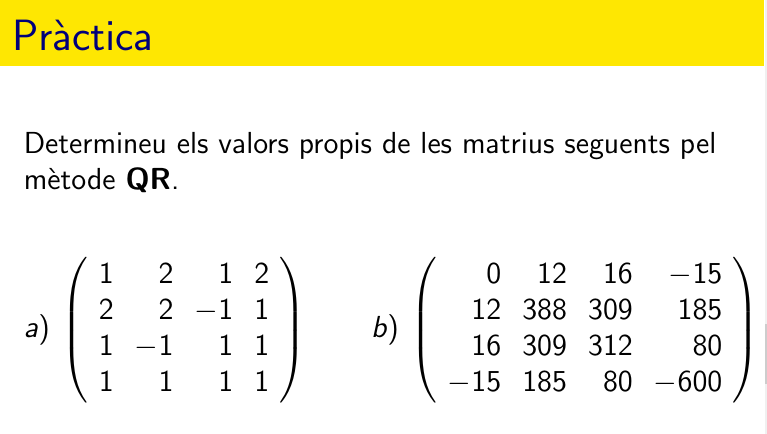

% veure practica5_exercici3.html
A = [ 1 2 1 2; 2 2 -1 1; 1 -1 1 1; 1 1 1 1 ];
H1 = hess(A);
it = 0;
while max(abs(diag(H1)-vap)) > 0.5e-2 && it < 1000
    [Q R] = qr(H1);
    H1 = R*Q;
    it = it + 1;
end

Unrecognized function or variable 'vap'.

it, diag(H1)

## 2.2 Matriu pseudoinversa. Singular Value Decomposition

### Part III. Practiquem ...

Documentació de MATLAB®, [valors singulars](https://es.mathworks.com/help/matlab/math/singular-values.html?searchHighlight=svd&s_tid=srchtitle)

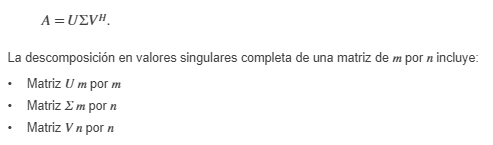

rng('default')
A = randn(6,3)               % matriu qualsevol
[U,S,V] = svd(A)             % U*S*V'-A
control = U*S*V'-A

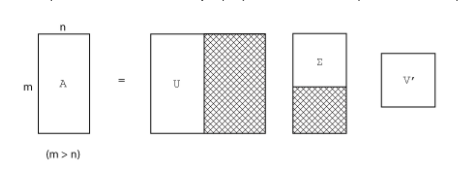

[U,S,V] = svd(A,0)
control =   U*S*V'-A

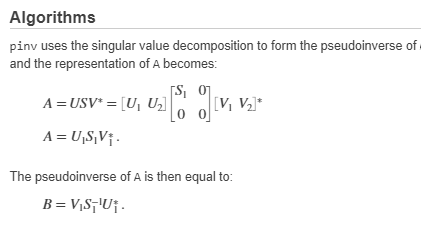

pinversa=pinv(A), B = V*inv(S)*U'
control_dreta = (B*A)*B, control_esquerra=(A*B)*A

#### Exercici 4.  Rutina svd

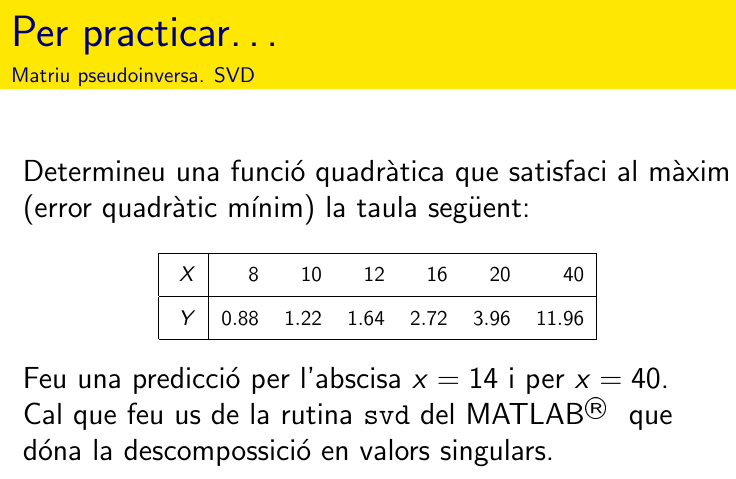

% veure practica5_exercici4
A = [8 0.88; 10 1.22; 12 1.64; 16 2.72; 20 3.96; 40 11.96];
scatter(A(:,1), A(:, 2))
[U S V] = svd(A)

U =      -0.15277     -0.33467     -0.27113     -0.34534     -0.41471     -0.70704
     -0.19152     -0.38265     -0.38142     -0.34717     -0.26451      0.69349
     -0.23064     -0.40684      0.85959     -0.14371     -0.13397     0.061556
     -0.31001     -0.38384     -0.14702      0.84295     -0.15539    -0.015539
     -0.39012     -0.31325     -0.14157     -0.16002      0.83016     -0.12192
     -0.79906      0.57498     0.021298    -0.058194     -0.16366     0.016743


S =        52.196            0
            0       3.2616
            0            0
            0            0
            0            0
            0            0


V =      -0.96999     -0.24314
     -0.24314      0.96999


r = length(find(diag(S)))

r =      2


Uhat = U(:,1:r)

Uhat =      -0.15277     -0.33467
     -0.19152     -0.38265
     -0.23064     -0.40684
     -0.31001     -0.38384
     -0.39012     -0.31325
     -0.79906      0.57498


Shat = S(1:r,1:r)

Shat =        52.196            0
            0       3.2616


z = Shat\Uhat'./diag(Shat);
c = V*z

c =     0.0077036     0.008814    0.0093808    0.0088834    0.0072986    -0.012857
    -0.030502    -0.034873    -0.037075    -0.034971    -0.028528     0.052499


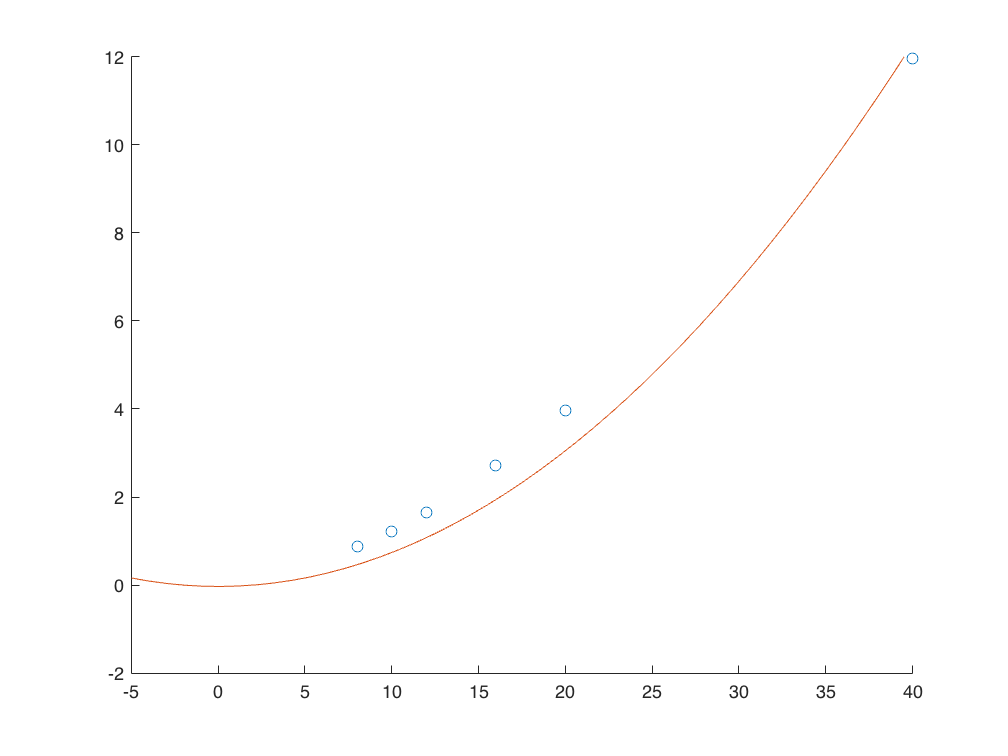

hold on
fplot(@(x)c(1)*x.^2+c(2))
hold off

#### Exercici 5.  Sistema  sobredeterminat

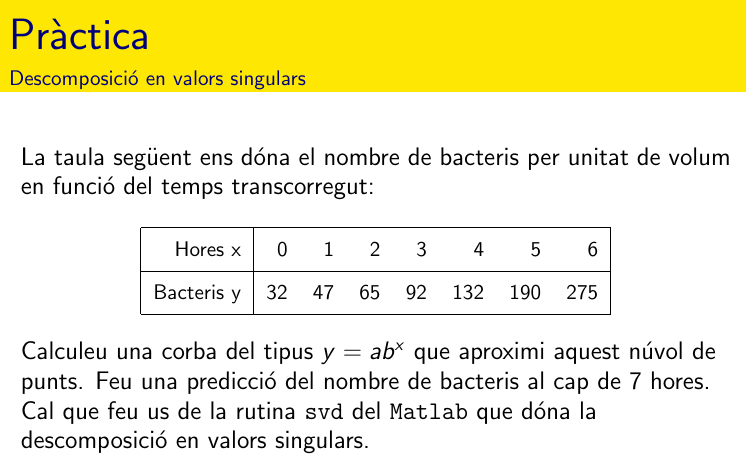

% veure practica5_exercici5

`Document preparat per M. Àngela Grau Gotés, 17 de març de 2022`